**Imagen Original**

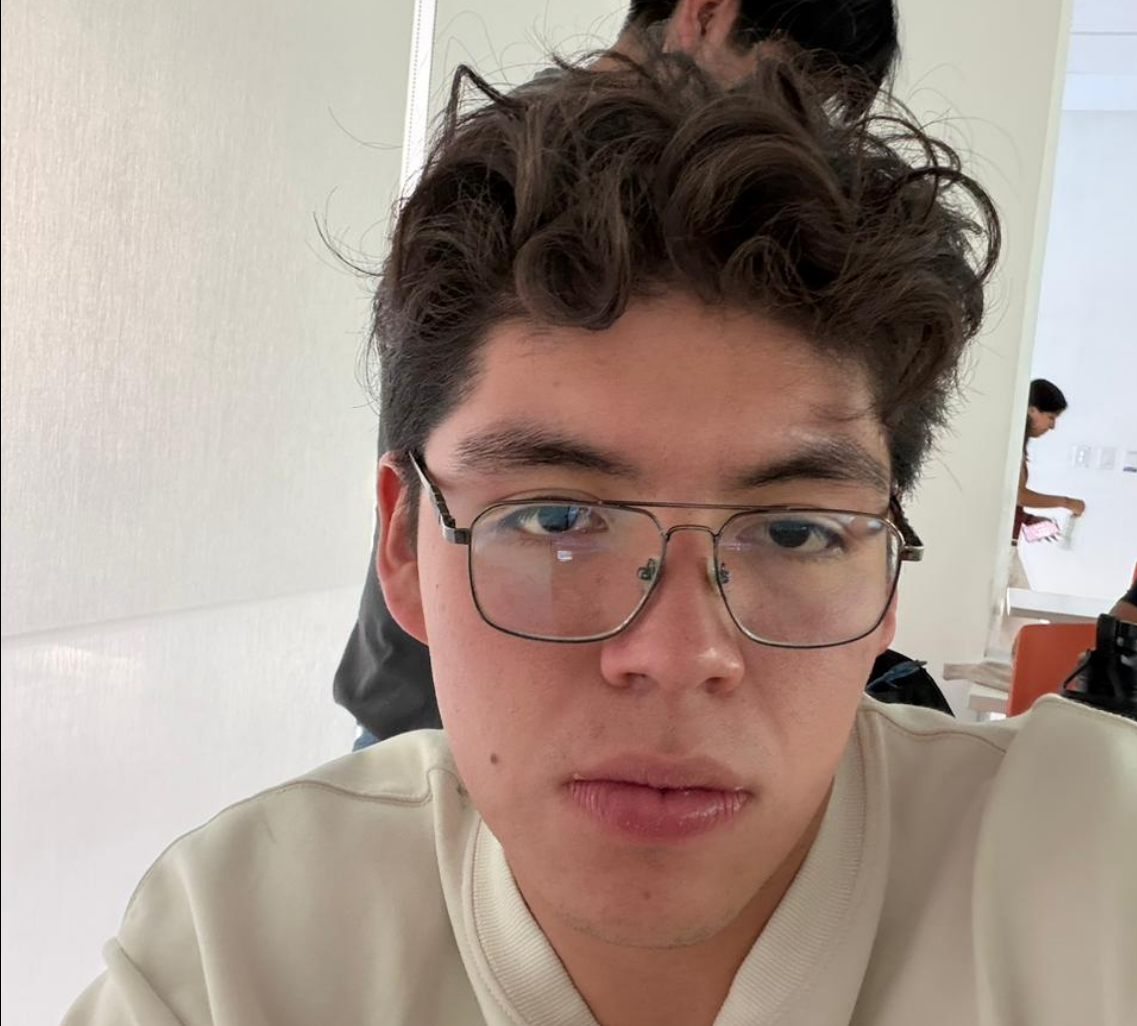

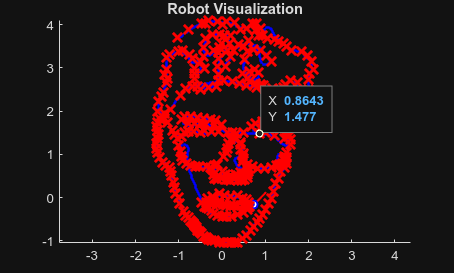

%% EXAMPLE: Differential drive vehicle following waypoints using the
% Pure Pursuit algorithm
%
% Copyright 2018-2019 The MathWorks, Inc.

%% Define Vehicle
R = 0.1;                % Wheel radius [m]
L = 0.5;                % Wheelbase [m]
dd = DifferentialDrive(R,L);

%% Waypoints
waypoints = [
    -1.0383,3.7032; -0.7691,3.8977; -0.4849,4.0323; -0.3885,4.0383;
    -0.3052,4.1105; -0.1164,4.0772; 0.0000,4.0000; 0.0946,4.0661;
    0.2778,4.0439; 0.4333,3.8995; 0.5721,3.9051; 0.6998,4.0217;
    0.7665,3.8662; 0.8386,3.7551; 0.7942,4.0328; 0.8997,3.9162;
    0.9386,3.7551; 1.0441,3.6885; 1.2162,3.6496; 1.3162,3.6163;
    1.4106,3.5774; 1.5000,3.5000; 1.6160,3.3942; 1.8270,3.3831;
    1.9658,3.2887; 2.0602,3.1499; 2.1213,2.9667; 2.0214,2.8834;
    1.9991,2.7445; 2.0000,2.5000; 1.8881,2.3392; 1.7937,2.1560;
    1.6604,2.2282; 1.7215,2.4447; 1.7548,2.6613; 1.5771,2.7057;
    1.4772,2.6279; 1.4106,2.5502; 1.2995,2.4947; 1.1607,2.5224;
    1.0000,2.5000; 0.9552,2.5946; 0.8775,2.6279; 0.7665,2.6502;
    0.6387,2.6779; 0.5777,2.7557; 0.6276,2.9111; 0.7553,2.9667;
    0.8442,2.9056; 0.4722,2.8778; 0.5110,3.1999; 0.7331,3.4331;
    0.5888,3.3720; 0.8997,3.4109; 1.0274,3.2832; 1.1440,3.1610;
    0.6165,3.6330; 0.5000,3.5000; 0.3722,3.5386; 0.2612,3.4053;
    0.2001,3.2554; 0.0779,3.0333; 0.1223,3.4109; 0.1779,3.5774;
    0.1834,3.7440; 0.0668,3.7551; -0.0609,3.7773; -0.2275,3.7718;
    -0.3774,3.6885; -0.4274,3.4664; -0.4274,3.2609; -0.1942,3.4109;
    -0.0220,3.5774; -0.0664,3.4830; -0.0831,3.3498; -0.0887,3.2165;
    -0.0998,3.0333; -0.0942,2.8556; -0.0720,2.7001; -0.1386,2.5724;
    -0.3052,2.5391; -0.5000,2.5000; -0.5717,2.5724; -0.6328,2.7668;
    -0.6328,2.8778; -0.4163,2.9944; -0.4940,3.1388; -0.6384,2.9889;
    -0.6883,3.2276; -0.7494,3.3109; -0.9049,3.3942; -1.0104,3.3887;
    -1.2269,3.3165; -1.2825,3.2498; -1.2936,2.9722; -1.3213,2.8556;
    -1.2603,2.7612; -1.2825,2.6724; -1.3547,2.4336; -1.3935,2.3392;
    -1.4713,2.2226; -1.5000,2.0000; -1.4102,1.9116; -1.3213,1.9450;
    -1.2047,2.0283; -0.9660,2.3670; -0.8383,2.5335; -0.6883,2.5780;
    0.0391,2.7112; 0.2445,2.6946; 0.4000,2.6446; 0.5610,2.6057;
    0.7887,2.5447; 1.1662,2.3947; 1.3495,2.3337; 1.3772,2.2226;
    1.3840,2.0885; 1.3893,1.9335; 1.4642,1.7516; 1.5016,1.5645;
    1.6567,1.8693; 1.7262,2.0564; 1.6086,1.7998; 1.5000,1.5000;
    1.4234,1.6542; 1.3182,1.7206; 1.1577,1.7759; 0.9363,1.7649;
    0.7702,1.7151; 0.6706,1.6542; 0.9363,1.6597; 1.0248,1.6652;
    1.2130,1.6652; 1.3403,1.6265; 1.5285,1.4217; 1.5784,1.3387;
    1.5894,1.2390; 1.4400,1.3608; 1.2130,1.4383; 1.0000,1.5000;
    0.8643,1.4770; 0.5000,1.5000; 0.3440,1.4936; 0.2388,1.4992;
    0.1336,1.5103; -0.0822,1.5379; -0.0103,1.6874; -0.1487,1.7815;
    -0.2594,1.8147; -0.4199,1.8368; -0.5583,1.8590; -0.7354,1.8867;
    -0.8793,1.8867; -0.9402,1.7981; -0.7797,1.7151; -0.6468,1.7095;
    -0.5029,1.7151; -0.3867,1.6929; -0.1819,1.6818; -0.2428,1.5324;
    -0.4088,1.5435; -0.5000,1.5000; -0.6690,1.5324; -0.7686,1.5269;
    -0.8683,1.5158; -0.9402,1.4051; -1.0288,1.3719; -1.0897,1.4494;
    -1.1506,1.5545; -1.2557,1.7372; -1.3221,1.8258; -1.4327,1.7970;
    -1.4901,1.7396; -1.5093,1.6486; -1.4949,1.5577; -1.4806,1.4716;
    -1.4901,1.3663; -1.5236,1.2562; -1.5141,1.1366; -1.4853,1.0457;
    -1.4423,0.9356; -1.3705,0.8016; -1.3131,0.7394; -1.2222,0.6916;
    -1.2000,0.6000; -1.1660,0.5055; -1.1346,0.3483; -1.1094,0.2415;
    -1.0843,0.1032; -1.0000,0.0000; -0.9775,-0.1356; -0.8957,-0.3116;
    -0.8422,-0.4048; -0.7814,-0.4656; -0.7382,-0.5303; -0.7010,-0.5617;
    -0.6696,-0.6048; -0.6441,-0.6421; -0.6000,-0.7000; -0.5618,-0.7578;
    -0.5245,-0.7911; -0.4764,-0.8348; -0.4366,-0.8911; -0.3704,-0.9342;
    -0.3174,-0.9640; -0.2446,-0.9938; -0.1651,-1.0037; -0.0492,-1.0302;
    0.0402,-1.0368; 0.1396,-1.0501; 0.2290,-1.0435; 0.2919,-1.0368;
    0.3482,-1.0302; 0.4641,-0.9408; 0.5668,-0.8679; 0.6462,-0.7686;
    0.7224,-0.6626; 0.8118,-0.5732; 0.8718,-0.4848; 0.9392,-0.3969;
    1.0008,-0.2796; 1.0711,-0.1419; 1.1444,-0.0100; 1.1854,0.1453;
    1.2411,0.3153; 1.3085,0.4502; 1.3583,0.6084; 1.4404,0.6905;
    1.4932,0.7901; 1.4785,0.8663; 1.4935,0.9304; 1.4896,1.0408;
    1.4383,0.9580; 1.4147,0.8752; 1.4000,0.8000; 1.3279,0.7648;
    1.2609,0.7333; 1.1387,0.6978; 0.9771,0.6742; 0.8234,0.6742;
    0.6972,0.7097; 0.5987,0.7727; 0.5040,0.8989; 0.4883,1.0211;
    0.4331,1.1117; 0.4370,1.2221; 0.4213,1.2852; 0.2991,1.3443;
    0.1966,1.3404; 0.1414,1.2576; 0.1335,1.1433; 0.1020,1.0447;
    0.0349,0.9422; -0.1149,0.7688; -0.1779,0.7412; -0.2173,0.6466;
    -0.1976,0.5401; 0.0000,0.6000; 0.0823,0.5441; 0.1847,0.5126;
    0.3188,0.5323; 0.4311,0.5899; 0.5066,0.5629; 0.5821,0.5278;
    0.6000,0.6000; 0.5471,0.7166; 0.4823,0.8407; 0.4661,0.9648;
    0.5767,0.6600; 0.5821,0.4766; 0.5282,0.4200; 0.4527,0.3957;
    0.3502,0.3957; 0.2908,0.4361; 0.2000,0.4000; 0.1398,0.4146;
    0.0966,0.4307; -0.0032,0.4334; -0.1003,0.4307; -0.1704,0.4361;
    -0.2709,0.6898; -0.3641,0.7208; -0.5194,0.7170; -0.6165,0.7170;
    -0.7291,0.7364; -0.8257,0.7857; -0.9109,0.8614; -0.9440,0.9467;
    -0.9582,1.0603; -1.0000,1.2000; -0.4703,-0.1130; -0.3469,-0.0217;
    -0.2210,0.0311; -0.0666,0.0880; 0.0512,0.0392; 0.1853,0.0271;
    0.3518,0.0392; 0.4763,-0.0186; 0.5651,-0.0541; 0.6077,-0.1180;
    0.6432,-0.2068; 0.6000,-0.2000; 0.5408,-0.1806; 0.4676,-0.1806;
    0.3553,-0.1879; 0.2650,-0.1806; 0.2000,-0.2000; 0.1064,-0.1781;
    0.0405,-0.1611; -0.0522,-0.1464; -0.1131,-0.1281; -0.1649,-0.1061;
    -0.2419,-0.1124; -0.2968,-0.1186; -0.3644,-0.1202; -0.4000,-0.2000;
    -0.3494,-0.2221; -0.3116,-0.2599; -0.2549,-0.3040; -0.1887,-0.3639;
    -0.1008,-0.4076; -0.0015,-0.4285; 0.1083,-0.4415; 0.2260,-0.4415;
    0.3645,-0.3971; 0.4926,-0.3344; 0.5815,-0.2742
];
%% Simulation parameters
sampleTime = 0.1;                                   % Sample time [s]
initPose = [waypoints(1,1); waypoints(1,2); 0];     % Arranca en el primer waypoint

% Tiempo dinámico segun longitud del path
pathLen = sum(vecnorm(diff(waypoints), 2, 2));
desiredV = 0.5;
tEnd = 0.94 * pathLen / desiredV;                    % 50% margen
tVec = 0:sampleTime:tEnd;

pose = zeros(3,numel(tVec));
pose(:,1) = initPose;

% Visualizador
viz = Visualizer2D;
viz.hasWaypoints = true;

%% Pure Pursuit Controller
controller = controllerPurePursuit;
controller.Waypoints = waypoints;
controller.LookaheadDistance = 0.25;% bajo para seguir contorno fielmente
controller.DesiredLinearVelocity = desiredV;
controller.MaxAngularVelocity = 5;



%% Simulation loop
r = rateControl(1/sampleTime);
for idx = 2:numel(tVec)
    % Pure Pursuit -> velocidades de rueda
    [vRef,wRef] = controller(pose(:,idx-1));
    [wL,wR] = inverseKinematics(dd,vRef,wRef);

    % Velocidades del cuerpo
    [v,w] = forwardKinematics(dd,wL,wR);
    velB = [v;0;w];
    vel = bodyToWorld(velB,pose(:,idx-1));

    % Integración discreta
    pose(:,idx) = pose(:,idx-1) + vel*sampleTime;

    % Visualización
    viz(pose(:,idx),waypoints);
    waitfor(r);
end

**Justificación del código y parámetros del controlador Pure Pursuit**

Para esta trayectoria se utilizó el algoritmo **Pure Pursuit** sobre un modelo de robot diferencial, partiendo del ejemplo oficial de MathWorks pero con varias modificaciones necesarias para que el cochecito pudiera trazar fielmente el contorno del rostro definido por los 327 waypoints exportados desde GeoGebra. Los parámetros físicos del vehículo (radio de rueda *R = 0.1 m* y distancia entre ejes *L = 0.5 m*) se conservaron del ejemplo original ya que únicamente afectan la cinemática interna sin influir en la geometría del trazo.

**Parámetros del controlador:**

- `LookaheadDistance = 0.25 m`**.** Es el parámetro más sensible del Pure Pursuit. Se redujo respecto al valor original de 0.5 m porque la trayectoria del rostro contiene detalles finos (cejas, ojos, nariz, boca) con curvaturas muy cerradas y waypoints separados por décimas de milímetro. Un *lookahead* grande hubiera suavizado en exceso esas regiones, cortando las esquinas y haciendo que el robot perdiera detalle facial. Un valor más pequeño generaró oscilaciones, por lo que 0.25 m se eligió como un valor entre fidelidad y estabilidad.

- `DesiredLinearVelocity = 0.5 m/s`**.** Se redujo a la mitad respecto al valor original (1 m/s) porque a mayor velocidad lineal, mayor es el radio mínimo que el robot puede trazar, lo que también provoca mal trazo de las curvas cerradas. Bajar la velocidad permite que el vehículo tenga el tiempo suficiente para reorientarse en los rasgos finos del rostro sin desbordar las restricciones de giro.

- `MaxAngularVelocity = 5 rad/s`**.** Este límite se mantuvo alto debido q que el contorno del rostro requiere cambios bruscos de orientación al pasar de un rasgo a otro . Si este valor fuera menor, la velocidad angular se saturaría en esos puntos y el robot no podría girar con la rapidez necesaria, produciendo derivas y pérdida de seguimiento. Con 5 rad/s se garantiza que la dinámica del controlador pueda corregir esos cambios bruscos sin saturarse.

- `SampleTime = 0.1 s`**.** Frecuencia de muestreo de 10 Hz, estándar para simulación cinemática; balance adecuado entre resolución temporal y costo computacional.

**Modificaciones respecto al código original de MathWorks:**

- **Pose inicial dinámica:** se sustituyó la posición fija `[10; 9; 0]` por `initPose = [waypoints(1,1); waypoints(1,2); 0]`, de modo que el robot arranca exactamente en el primer waypoint del rostro. Esto evita un transitorio inicial donde el vehículo viajaría en línea recta desde un punto arbitrario hasta el primer waypoint, lo que distorsionaría el trazo.

- **Tiempo de simulación calculado:** se reemplazó el valor fijo `tf = 52 s` por un cálculo dinámico basado en la longitud real del recorrido:

                                            pathLen = sum(vecnorm(diff(waypoints), 2, 2));  

                                            tEnd = 0.94 * pathLen / desiredV;

El factor 0.94 se ajustó de forma empírica: garantiza que la simulación termine exactamente cuando el robot completa el trazo, sin dejar tiempo extra durante el cual Pure Pursuit hace círculos alrededor del último waypoint.

**Obtención de puntos:**

Para obtener los puntos se importó la imagen original a Geogebra y se trazaron los puntos en los detalles del rostro y se usó un arreglo para sacar los puntos totales.